# Quadruped robot optimization

# Step 1.5 - Search coefficent of PD-controll

## Set parameters for optimization

Define the desired velocity, type of actuators and total gait time (each point is evenly spaced within this time)

clc; clear all;

robotParameters; % Paramaters of robot and simulation
typeBody = 1; % Body's type is without spine 
numPoints = 6; % Number of joint angle points
mdlName = 'QR_Unitree'; % Main model
open_system(mdlName);

Choose data for optimize:

path = "bouncing_1_Motor_optimizedData_22Apr22_1512";

To reduce the search space, scale the angle waypoints and solve the optimization algorithm with integer parameters. This scaling factor is from degrees to an integer.

scalingFactor = 3;

use_previous = true;
p0 = [90 10 90 10];

## Set optimization options

Compile the model to run a single simulation faster:

accelFlag = true;

**Not recommend use! **Use parallel computing on multiple cores on your machine or on a cluster or cloud

parallelFlag = true;  

The options for the genetic algorithm are defined using the [`optimoptions`](https://www.mathworks.com/help/optim/ug/optim.problemdef.optimizationproblem.optimoptions.html) function.

Set size of population GA

opts = optimoptions('ga');
population_size = 40;

Set maximum of generation

opts.MaxGenerations = 10;

Options for GA:

opts.Display = 'iter';
opts.PopulationSize = population_size;
opts.PlotFcn = {@gaplotbestf, @gaplotexpectation}; 
opts.UseParallel = parallelFlag;
if use_previous
    opts.InitialPopulationMatrix = repmat(p0,[population_size 1]);
end

## Set joint angle bounds and constraints

% [FemurPropotional FemurDiff TibiaPropotional TibiaDiff]
upperBnd = [300 50 300 50] ...
            /scalingFactor;
lowerBnd = [40 5 40 5] ...
            /scalingFactor;

Run commands to set up parallel/accelerated simulation

doSpeedupTasks;

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


## Run optimization

Here we use the [`ga`](https://www.mathworks.com/help/gads/ga.html) function from Global Optimization Toolbox to optimize the walking gait, with **simulateQuadrupedRobot** as the fitness function.

costFcn = @(p)CostFcnPDcontroll(p,mdlName,scalingFactor,path);
disp(['Running optimization. Population: ' num2str(opts.PopulationSize) ...
       ', Max Generations: ' num2str(opts.MaxGenerations)])

Running optimization. Population: 40, Max Generations: 10



Single objective optimization:
4 Variable(s)
4 Integer variable(s)

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1               80      -3.404e+07      -1.583e+07        0
    2              118      -3.734e+07      -2.021e+07        0
    3              156       -3.76e+07      -2.071e+07        0
    4              194      -3.824e+07      -2.178e+07        0
    5              232      -3.946e+07      -2.438e+07        0
    6              270      -3.946e+07      -2.371e+07        1
    7              308      -3.946e+07      -2.621e+07        2
    8              346      -3.946e+07      -2.555e+07        3
    9              384      -3.946e+07      -2.531e+07        4
   10              422      -3.946e+07      -2.607e+07  

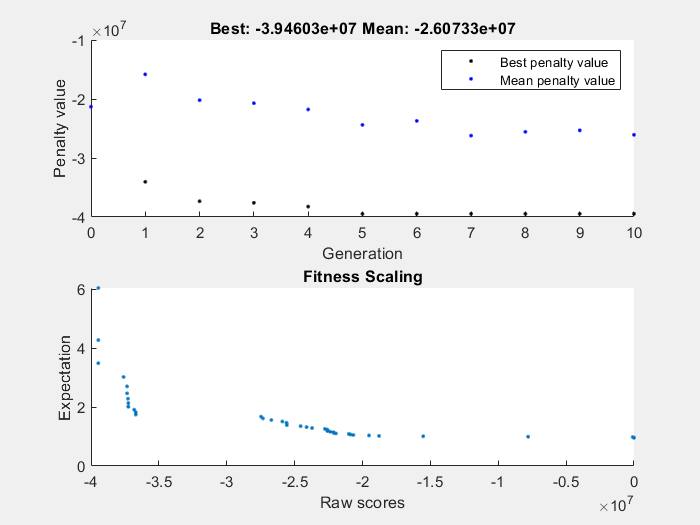

Optimization terminated: maximum number of generations exceeded.


[pFinal,reward,~,output,last_population,last_scores] = ga(costFcn,4,[],[],[],[], ... 
                      lowerBnd,upperBnd,[],1:4,opts);

disp(['Final reward function value: ' num2str(reward)])

Final reward function value: -39460263.9859


set_param(mdlName,'SimMechanicsOpenEditorOnUpdate','on'); % On Mechanics Explorers
% set_param(mdlName,'FastRestart','off'); % Off Fast Restart
% delete(gcp('nocreate')); % Shutdown parallel pool

## Analyze and save results

Convert from optimization integer search space to trajectories in radians

indiv = 0; % The best individ is first
if indiv == 0
    pScaled = scalingFactor*pFinal;
else
    pScaled = scalingFactor*last_population(indiv,:);
    reward = last_scores(indiv,:);
end

k_p_fem =  pScaled(1); %213
k_d_fem =  pScaled(2)/10;% 2.7
k_i_fem = 0;
k_p_tib =  pScaled(3);% 242
k_d_tib =  pScaled(4)/10;% 4.5
k_i_tib = 0;

## Simulate optimize model and plot figures

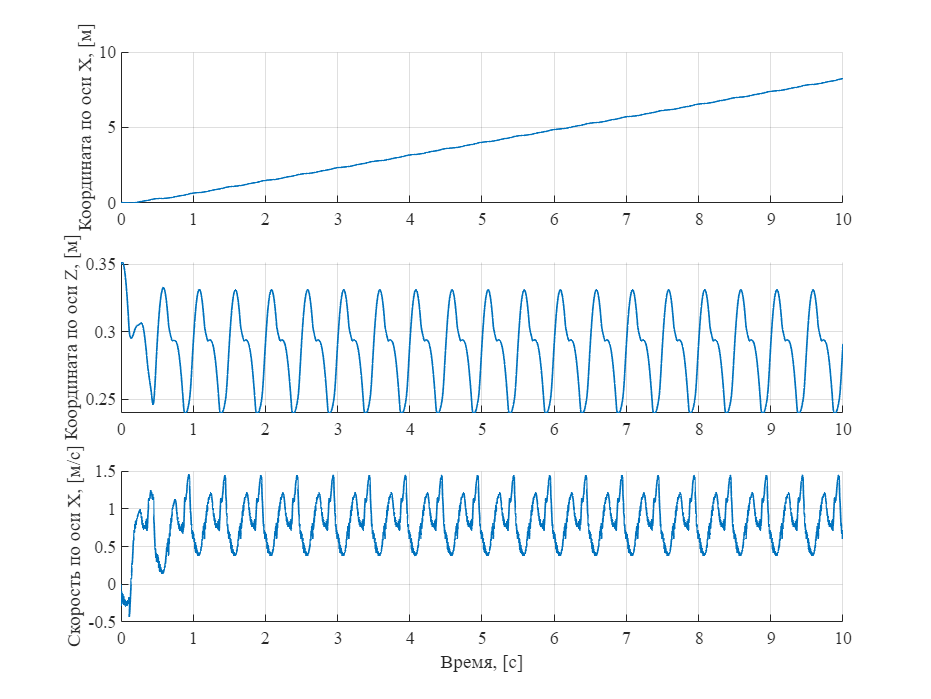

new_run = 0;
use_previous = 0;
actuatorType = 1;
run_previous_ctrl;

PlotCoM_xyz;

disp(['Mean Z position: ' num2str(mean_Z) ...
       ' [m], mean velocity forward: ' num2str(mean_velocity)...
       ' [m/s], Cost Of Transport: ' num2str(CoT)])

Mean Z position: 0.28473 [m], mean velocity forward: 0.81796 [m/s], Cost Of Transport: 2.6017


## Cleanup

Close the model and, if a parallel pool was created, delete it.

doCleanup = false;
if doCleanup
    close all force; % Clear figures
    bdclose(mdlName);
    if parallelFlag
        delete(gcp('nocreate'));
    end
end